## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a quadratic strain basis.

SorosimLink (`L1`) and SorosimLinkage (`T1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

Error using load
Unable to find file or directory 'SoftManipulator.mat'.

To see the properties of `L1`

L1

To see the properties of S`1`

T1

To see the problem definition:

T1.plotq0

The result should be:

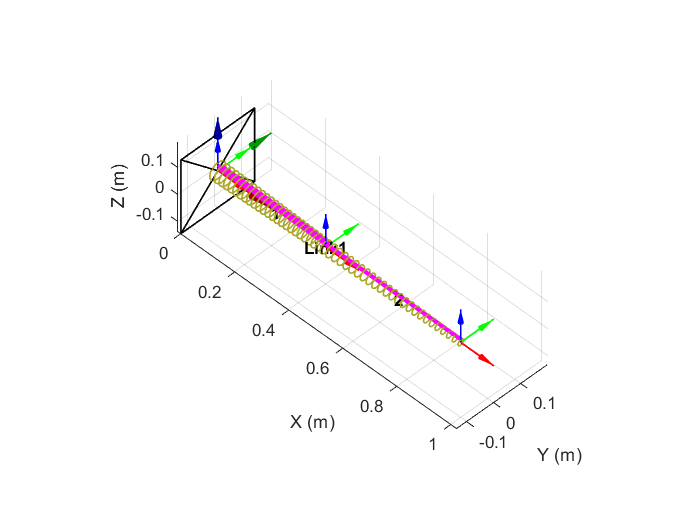

The beam is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

q=T1.statics;

You will be prompted to enter the actuation force in the command window. Enter -5, -10, -15, -20 N as the input actuation forces into cables 1, 2, 3 and 4 respectively. 

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

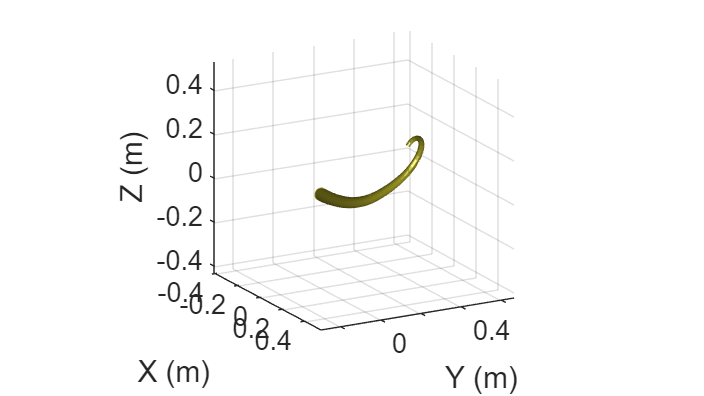

### **Dynamics**

For dynamics problem, type:

[t,qqd]=T1.dynamics([],'ode15s');

The actuation input to the cables can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.